## Lecture 19, Trefethen and Bau:

(make sure that mgs and clgs are in the same

directory as this lecture19.mlx script)

# Stability of Least Squares Algorithms

We compare the stability characteristics of least squares, solved via

matlab's \ operator, the modified Gram-Schmidt algorithm, and SVD

*The problem is to interpolate the function (1/Z)exp(sin(4t)) over the interval [0,1], using a polynomial of degree 14. Z = 2006.787454080206;*

*The normalization is introduced so that the coefficients of the interpolations are such that the last one is 1.*

## *Setup:*

clear, close all
Z = 2006.787453080206;
m=100; % number of interpolation knots
n=15; %n-1 is the degree of the polynomial
t=(0:m-1)'/(m-1); % breakup the [0,1] interval
A=[];
for ii = 1:n
    A = [A t.^(ii-1)];
end
b = exp(sin(4*t))/Z;
plot(t,b)
title('exp(sin(t))')
xlabel('t')
grid

## Solving Least Squares via matlab's \ operator:

the backslash operator \ is doing Householder triangulation with column pivoting (we'll talk about pivoting in another lecture). This is a basic work horse of matlab. It is a stabilized version of Householder.

x=A\b; % least squares estimate
y = A*x; % Pb = y
hold

Current plot held


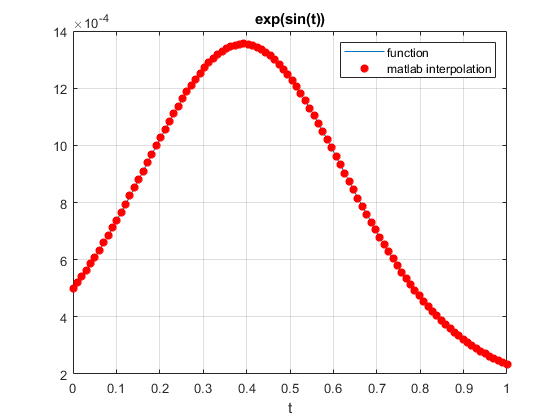

plot(t,y,'r*','linewidth',2)
legend('function','matlab interpolation')

We will only look at a single coefficient, x(15) (you are welcomed to 

look at the whole x).

The plot shows good agreement between the function b (in black) and the interpolation y (in red). The last coefficient is

x(15)=1.000000080854117

Refer to Lecture 18 Theorem 18.1:

kappa = cond(A);
theta=asin(norm(b-y))/norm(b);
eta = norm(A)*norm(x)/norm(y);

fprintf('kappa=%e',kappa);

kappa=2.271777e+10

fprintf('theta=%e',theta);

theta=3.746111e-06

fprintf('eta=%e',eta);

eta=2.103559e+05

kappa ~ 10e10 indicates that A is very ill-conditioned.

theta ~ 1e-6 indicates that b can be fit very closely by a polynomial

of degree 14

eta ~ 1e5 indicates that its somewhere in the middle of the range 1 and kappa.

## Using Gram-Schmidt (algorithm 7.1 and 8.1)

Earlier we had developed a QR decomposition based on 

Gram Schmidt. We'll use these to find the coefficients.

These are, respectively, xc and xm.

[Q,R]=clgs(A);
xc=R\(Q'*b);
[Q,R]=mgs(A);
xm=R\(Q'*b);

xc(15) =  0.000757169621142

xm(15) = 0.981684027615913

## Using the Normal Equations:

we will use these to find the coefficients xn

xn=(A'*A)\(A'*b);

xn(15) = -0.422765743212018

This results in terrible answers. The normal equations are the ones that appear most often in least squares texts. For full rank and well conditioned problems, the method leads to good resuts, but clearly, not on an ill-conditioned problem. 

## Using SVD: 

[U,S,V]=svd(A,0);
xs=V*(S\(U'*b));

xs(15) = 1.000000131410743

is the most accurate of these results. 

This is because *SVD for a full rank least squares problem is backward*

*stable.*

## *Comparison of the various interpolating approximations:*

*we will plot A*(xi-xs), where xi = x, xc, xm, and xn.*

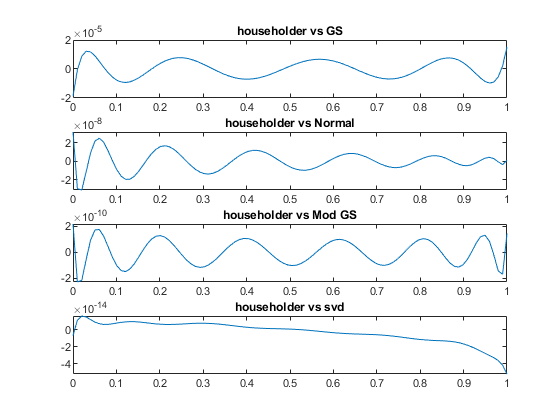

figure
subplot(4,1,4),plot(t,A*(x-xs)), title('householder vs svd')
subplot(4,1,1),plot(t,A*(x-xc)), title('householder vs GS')
subplot(4,1,3),plot(t,A*(x-xm)), title('householder vs Mod GS')
subplot(4,1,2),plot(t,A*(x-xn)), title('householder vs Normal')